clc; clear; close all;

## LAB 1 - grupa 1a

Model ciągły z instrukcji: dy(t)/dt + a0*y(t) = b0*u(t)

Lewostronna aproksymacja pochodnej: (y(k)-y(k-1))/td + a0*y(k) = b0*u(k)

Model dyskretny w postaci ogólnej: y(k) = a1*y(k-1) + b1*u(k)

gdzie: a1 = 1/(1 + a0*td) b1 = (b0*td)/(1 + a0*td)

Do estymacji przyjmujemy więc równanie liniowe: Y = Phi*theta Y = y(k) Phi = [y(k-1) u(k)] theta = [a1; b1]

## Dane

load('MiI_P1_grupa_1a.mat');

t  = u.time(:);
u  = u.signals.values(:);
y1 = y_cz1.signals.values(:);
y2 = y_cz2.signals.values(:);
td = double(td);

%1a
zakres_cz1 = [2.0 5.0];
zakres_cz2 = [3.0 4.0];

N = length(t);
N_est = floor(N/2);           % estymacja na części danych
k_est = (2:N_est)';           % wiersze użyte do estymacji

% Macierze wagowe diagonalne:
% brak informacji o korelacji błędów między pomiarami, więc wybór macierzy
% diagonalnej jest naturalny.
poziomy_wag = [2 5 10];       % W1, W2, W3

## Analiza dla obu czujników


Czujnik 1
Zakres dokładniejszych wskazań: [2.00, 5.00]
Liczba dokładniejszych danych w zbiorze estymacyjnym: 1026 z 1499

MNK
a1 = 0.87088115
b1 = 0.05140835
Transmitancja operatorowa: G(z) = 0.05140835 / (1 - 0.87088115 z^{-1})
Zgodność replikatywna: srednia(e) = +1.90515209e-03, MSE = 1.41889122e-02, var = 1.41900126e-02
Zgodność predykatywna: srednia(e) = +1.42514998e-02, MSE = 1.96421888e-02, var = 1.94455654e-02

W1
a1 = 0.88097573
b1 = 0.04732179
Transmitancja operatorowa: G(z) = 0.04732179 / (1 - 0.88097573 z^{-1})
Zgodność replikatywna: srednia(e) = +2.70491154e-03, MSE = 1.42091273e-02, var = 1.42065462e-02
Zgodność predykatywna: srednia(e) = +2.21834217e-02, MSE = 1.70002343e-02, var = 1.65136346e-02

W2
a1 = 0.88848854
b1 = 0.04428432
Transmitancja operatorowa: G(z) = 0.04428432 / (1 - 0.88848854 z^{-1})
Zgodność replikatywna: srednia(e) = +3.25673480e-03, MSE = 1.42448520e-02, var = 1.42389920e-02
Zgodność predykatywna: sr

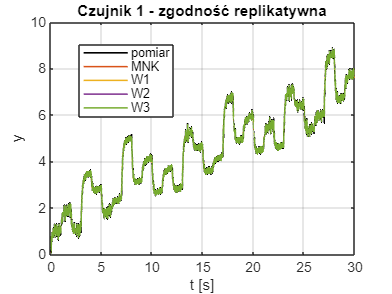

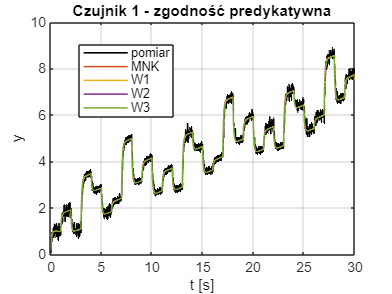

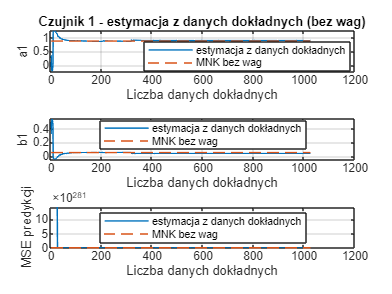


Czujnik 1 - punkt 10/11
Porównanie z MNK bez wag wykonano dla estymacji tylko z danych dokładnych.
Minimalna liczba równań potrzebna do estymacji dwóch parametrów wynosi 2,
natomiast wpływ liczby danych dokładnych pokazano na wykresie.


wyniki_cz1 = analiza_czujnika('Czujnik 1', y1, u, t, td, zakres_cz1, k_est, poziomy_wag);


Czujnik 2
Zakres dokładniejszych wskazań: [3.00, 4.00]
Liczba dokładniejszych danych w zbiorze estymacyjnym: 382 z 1499

MNK
a1 = 0.87957269
b1 = 0.04799209
Transmitancja operatorowa: G(z) = 0.04799209 / (1 - 0.87957269 z^{-1})
Zgodność replikatywna: srednia(e) = +1.37383311e-03, MSE = 9.94705249e-03, var = 9.94848123e-03
Zgodność predykatywna: srednia(e) = +1.08807916e-02, MSE = 1.42263801e-02, var = 1.41126927e-02

W1
a1 = 0.88619504
b1 = 0.04538468
Transmitancja operatorowa: G(z) = 0.04538468 / (1 - 0.88619504 z^{-1})
Zgodność replikatywna: srednia(e) = +1.08957429e-03, MSE = 9.94279326e-03, var = 9.94492106e-03
Zgodność predykatywna: srednia(e) = +9.05084048e-03, MSE = 1.23972893e-02, var = 1.23194781e-02

W2
a1 = 0.89445146
b1 = 0.04213906
Transmitancja operatorowa: G(z) = 0.04213906 / (1 - 0.89445146 z^{-1})
Zgodność replikatywna: srednia(e) = +6.78098876e-04, MSE = 9.95534495e-03, var = 9.95820453e-03
Zgodność predykatywna: sre

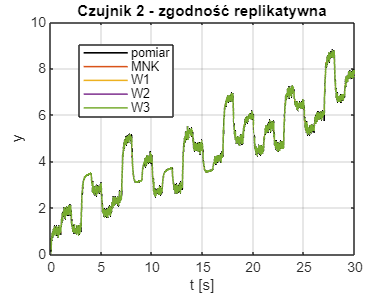

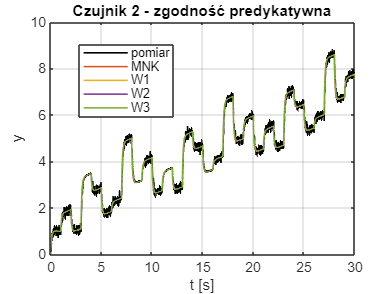

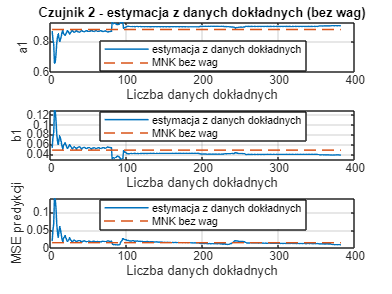


Czujnik 2 - punkt 10/11
Porównanie z MNK bez wag wykonano dla estymacji tylko z danych dokładnych.
Minimalna liczba równań potrzebna do estymacji dwóch parametrów wynosi 2,
natomiast wpływ liczby danych dokładnych pokazano na wykresie.


wyniki_cz2 = analiza_czujnika('Czujnik 2', y2, u, t, td, zakres_cz2, k_est, poziomy_wag);

## ===== Funkcje lokalne =====

function wyniki = analiza_czujnika(nazwa, y, u, t, td, zakres, k_est, poziomy_wag)
    fprintf('\n==================================================\n');
    fprintf('%s\n', nazwa);
    fprintf('Zakres dokładniejszych wskazań: [%.2f, %.2f]\n', zakres(1), zakres(2));

    % Wiersz równania uznajemy za dokładniejszy, gdy wartość y(k)
    % należy do dokładniejszego zakresu pracy czujnika.
    dokladne = (y(k_est) >= zakres(1)) & (y(k_est) <= zakres(2));
    fprintf('Liczba dokładniejszych danych w zbiorze estymacyjnym: %d z %d\n', ...
        sum(dokladne), numel(k_est));

    etykiety = {'MNK', 'W1', 'W2', 'W3'};
    wektory_wag = cell(1,4);
    wektory_wag{1} = ones(numel(k_est),1);

    for i = 1:3
        w = ones(numel(k_est),1);
        w(dokladne) = poziomy_wag(i);
        wektory_wag{i+1} = w;
    end

    wyniki_modele = repmat(struct(), 1, numel(etykiety));

    for i = 1:numel(etykiety)
        theta = estymuj_mnk_wazone(y, u, k_est, wektory_wag{i});
        [y_rep, y_pred] = odpowiedz_modelu(y, u, theta);

        e_rep  = y(2:end) - y_rep(2:end);
        e_pred = y(2:end) - y_pred(2:end);

        miary_rep  = miary_bledow(e_rep);
        miary_pred = miary_bledow(e_pred);

        wyniki_modele(i).etykieta = etykiety{i};
        wyniki_modele(i).theta = theta;
        wyniki_modele(i).y_rep = y_rep;
        wyniki_modele(i).y_pred = y_pred;
        wyniki_modele(i).miary_rep = miary_rep;
        wyniki_modele(i).miary_pred = miary_pred;

        fprintf('\n%s\n', etykiety{i});
        fprintf('a1 = %.8f\n', theta(1));
        fprintf('b1 = %.8f\n', theta(2));
        fprintf('Transmitancja operatorowa: G(z) = %.8f / (1 - %.8f z^{-1})\n', ...
            theta(2), theta(1));
        fprintf('Zgodność replikatywna: srednia(e) = %+.8e, MSE = %.8e, var = %.8e\n', ...
            miary_rep.srednia, miary_rep.mse, miary_rep.wariancja);
        fprintf('Zgodność predykatywna: srednia(e) = %+.8e, MSE = %.8e, var = %.8e\n', ...
            miary_pred.srednia, miary_pred.mse, miary_pred.wariancja);
    end

    T = table('Size', [numel(etykiety), 9], ...
        'VariableTypes', {'string','double','double','double','double','double','double','double','double'}, ...
        'VariableNames', {'Metoda','a1','b1','Rep_srednia','Rep_MSE','Rep_wariancja', ...
                          'Pred_srednia','Pred_MSE','Pred_wariancja'});

    for i = 1:numel(etykiety)
        T.Metoda(i) = string(wyniki_modele(i).etykieta);
        T.a1(i) = wyniki_modele(i).theta(1);
        T.b1(i) = wyniki_modele(i).theta(2);
        T.Rep_srednia(i) = wyniki_modele(i).miary_rep.srednia;
        T.Rep_MSE(i) = wyniki_modele(i).miary_rep.mse;
        T.Rep_wariancja(i) = wyniki_modele(i).miary_rep.wariancja;
        T.Pred_srednia(i) = wyniki_modele(i).miary_pred.srednia;
        T.Pred_MSE(i) = wyniki_modele(i).miary_pred.mse;
        T.Pred_wariancja(i) = wyniki_modele(i).miary_pred.wariancja;
    end

    fprintf('\nTabela zbiorcza - %s\n', nazwa);
    disp(T);

    % Porównanie odpowiedzi modelu z danymi pomiarowymi
    figure('Name', [nazwa ' - zgodność replikatywna'], 'Color', 'w');
    plot(t, y, 'k', 'LineWidth', 1.1); hold on;
    for i = 1:numel(etykiety)
        plot(t, wyniki_modele(i).y_rep, 'LineWidth', 1.0);
    end
    grid on;
    xlabel('t [s]'); ylabel('y');
    title([nazwa ' - zgodność replikatywna']);
    legend([{'pomiar'}, etykiety], 'Location', 'best');

    figure('Name', [nazwa ' - zgodność predykatywna'], 'Color', 'w');
    plot(t, y, 'k', 'LineWidth', 1.1); hold on;
    for i = 1:numel(etykiety)
        plot(t, wyniki_modele(i).y_pred, 'LineWidth', 1.0);
    end
    grid on;
    xlabel('t [s]'); ylabel('y');
    title([nazwa ' - zgodność predykatywna']);
    legend([{'pomiar'}, etykiety], 'Location', 'best');

    % Punkt 10 / 11:
    % estymacja tylko z danych dokładnych, bez macierzy wag,
    % oraz porównanie z klasycznym MNK na całym zbiorze estymacyjnym.
    k_dokladne = k_est(dokladne);
    analiza_liczby_danych(nazwa, y, u, k_dokladne, wyniki_modele(1).theta, wyniki_modele(1).miary_pred.mse);

    wyniki.modele = wyniki_modele;
    wyniki.tabela = T;
    wyniki.k_dokladne = k_dokladne;
    wyniki.td = td;
end

function theta = estymuj_mnk_wazone(y, u, k, w)
    Y = y(k);
    Phi = [y(k-1), u(k)];
    W = diag(w(:));
    theta = (Phi' * W * Phi) \ (Phi' * W * Y);
end

function [y_rep, y_pred] = odpowiedz_modelu(y, u, theta)
    a1 = theta(1);
    b1 = theta(2);
    N = length(y);

    y_rep = zeros(N,1);
    y_pred = zeros(N,1);

    y_rep(1) = y(1);
    y_pred(1) = y(1);

    for k = 2:N
        y_rep(k) = a1 * y(k-1) + b1 * u(k);
        y_pred(k) = a1 * y_pred(k-1) + b1 * u(k);
    end
end

function m = miary_bledow(e)
    m.srednia = mean(e);
    m.mse = mean(e.^2);
    m.wariancja = var(e, 0);   % wariancja z próby
end

function analiza_liczby_danych(nazwa, y, u, k_dokladne, theta_MNK, mse_MNK)
    if numel(k_dokladne) < 2
        fprintf('\n%s: zbyt mało dokładnych danych do osobnej estymacji.\n', nazwa);
        return;
    end

    n_test = 2:numel(k_dokladne);
    a1_hist = zeros(size(n_test));
    b1_hist = zeros(size(n_test));
    mse_hist = zeros(size(n_test));

    for i = 1:numel(n_test)
        n = n_test(i);
        k_uzyte = k_dokladne(1:n);
        theta_n = estymuj_mnk_wazone(y, u, k_uzyte, ones(n,1));
        [~, y_pred_n] = odpowiedz_modelu(y, u, theta_n);
        e_pred_n = y(2:end) - y_pred_n(2:end);

        a1_hist(i) = theta_n(1);
        b1_hist(i) = theta_n(2);
        mse_hist(i) = mean(e_pred_n.^2);
    end

    figure('Name', [nazwa ' - liczba danych dokładnych'], 'Color', 'w');

    subplot(3,1,1);
    plot(n_test, a1_hist, 'LineWidth', 1.0); hold on;
    plot([n_test(1) n_test(end)], [theta_MNK(1) theta_MNK(1)], '--');
    grid on;
    xlabel('Liczba danych dokładnych'); ylabel('a1');
    title([nazwa ' - estymacja z danych dokładnych (bez wag)']);
    legend('estymacja z danych dokładnych', 'MNK bez wag', 'Location', 'best');

    subplot(3,1,2);
    plot(n_test, b1_hist, 'LineWidth', 1.0); hold on;
    plot([n_test(1) n_test(end)], [theta_MNK(2) theta_MNK(2)], '--');
    grid on;
    xlabel('Liczba danych dokładnych'); ylabel('b1');
    legend('estymacja z danych dokładnych', 'MNK bez wag', 'Location', 'best');

    subplot(3,1,3);
    plot(n_test, mse_hist, 'LineWidth', 1.0); hold on;
    plot([n_test(1) n_test(end)], [mse_MNK mse_MNK], '--');
    grid on;
    xlabel('Liczba danych dokładnych'); ylabel('MSE predykcji');
    legend('estymacja z danych dokładnych', 'MNK bez wag', 'Location', 'best');

    fprintf('\n%s - punkt 10/11\n', nazwa);
    fprintf('Porównanie z MNK bez wag wykonano dla estymacji tylko z danych dokładnych.\n');
    fprintf('Minimalna liczba równań potrzebna do estymacji dwóch parametrów wynosi 2,\n');
    fprintf('natomiast wpływ liczby danych dokładnych pokazano na wykresie.\n');
end